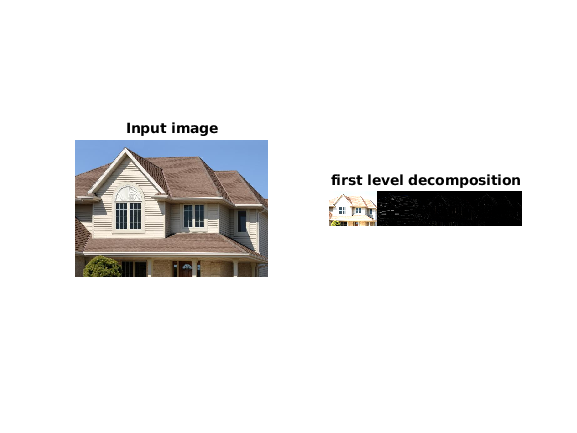

% read input image 

Input_image=imread('roof.jpeg');

%red component of colour image 

Red_Input_image=Input_image(:,:,1);

%GREEN COMPONENT OF COLOUR IMAGE 

Green_Input_image=Input_image(:,:,2);

%blue component of colour image 

Blue_Input_image=Input_image(:,:,3);

%applying two dimensional discrete wavelet transformation

[LLr,LHr,HLr,HHr]=dwt2(Red_Input_image,'haar');
[LLg,LHg,HLg,HHg]=dwt2(Green_Input_image,'haar');
[LLb,LHb,HLb,HHb]=dwt2(Blue_Input_image,'haar');



%first level decomposition 

First_Level_Decomposition(:,:,1)=[LLr,LHr,HLr,HHr];
First_Level_Decomposition(:,:,2)=[LLg,LHg,HLg,HHg];
First_Level_Decomposition(:,:,3)=[LLb,LHb,HLb,HHb];

First_Level_Decomposition=uint8(First_Level_Decomposition);


% plotting  the Input_image ----
subplot(1,2,1);
imshow(Input_image);
title('Input image' );

%plotting the output first level dicomsed image __
subplot(1,2,2);
imshow(First_Level_Decomposition,[]);
title('first level decomposition');